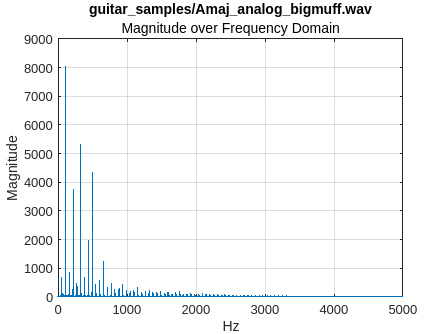

Error using saveas
Invalid or missing path: img/magnitude_plots/magnitude_Amaj_analog_bigmuff.png

Error in plotAudioFrequency (line 30)
    saveas(gcf, fullfile('img/magnitude_plots', ['magnitude_' name '.png']));

clear;
import plotAudioFrequency.*

% Define the directory containing the audio files
audioDir = 'guitar_samples';
files = dir(fullfile(audioDir, '*.wav'));

% Loop over each file in the directory
for i = 1:length(files)
    % Construct the full file path
    filePath = fullfile(audioDir, files(i).name);

    % Call the plotAudioFrequency function on each file
    plotAudioFrequency(filePath);
end